# Parameter setting

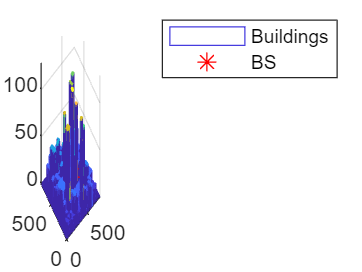

clc;
clear;
load('BldMap_trueHeight.mat');
%BS2Dloc=rand(1,2)*400+[200,200];%基站2D坐标在[200,600]x[200,600]
BS2Dloc=[400,400];
Bsloc_BldHeight=max([smallBldMap(ceil(BS2Dloc(1)),ceil(BS2Dloc(2))), 
                     smallBldMap(ceil(BS2Dloc(1)),floor(BS2Dloc(2))),
                     smallBldMap(floor(BS2Dloc(1)),ceil(BS2Dloc(2))), 
                     smallBldMap(floor(BS2Dloc(1)),floor(BS2Dloc(2)))]);

mesh(smallBldMap);
hold on;
%BSHeight=Bsloc_BldHeight+0.01;%基站高度取建筑物上的20m
BSHeight=Bsloc_BldHeight+0.01;
%BSHeight = 15;
BSloc=[BS2Dloc,BSHeight];
plot3(BSloc(1),BSloc(2),BSloc(3),'r*','markersize',10);
legend('Buildings','BS');
UAVheight=max(max(smallBldMap));%139m,Building最大高度129m
hold off;


%获取Building的3D坐标，每个（i，j）上的建筑物上的三维坐标，高度是建筑物最大高度
[NUM_X,NUM_Y]=size(smallBldMap);
Bld_grid_3Dloc=cell(NUM_X,NUM_Y);%NUM_X x NUM_Y x3 每个网格的3D位置
UAVgrid_Bs_dist=zeros(NUM_X,NUM_Y);
for i = 1:NUM_X
    for j = 1:NUM_Y
        temp = [i,j,smallBldMap(i,j)];
        Bld_grid_3Dloc{i,j} = temp;
        temp = [i,j,UAVheight];
        UAVgrid_Bs_dist(i,j) = norm(temp-BSloc);
    end
end

Map_grid = reshape(Bld_grid_3Dloc,[NUM_X*NUM_Y,1]);
Map_grid = cell2mat(Map_grid);
Map_grid(:,3) = UAVheight;

% 计算LSM (物理地图 2 LSM)
LSM = create_LSM(BSloc,smallBldMap,UAVheight);

     1

     2

     3

     4

     5

     6

     7

     8

     9

    10

    11

    12

    13

    14

    15

    16

    17

    18

    19

    20

    21

    22

    23

    24

    25

    26

    27

    28

    29

    30

    31

    32

    33

    34

    35

    36

    37

    38

    39

    40

    41

    42

    43

    44

    45

    46

    47

    48

    49

    50

    51

    52

    53

    54

    55

    56

    57

    58

    59

    60

    61

    62

    63

    64

    65

    66

    67

    68

    69

    70

    71

    72

    73

    74

    75

    76

    77

    78

    79

    80

    81

    82

    83

    84

    85

    86

    87

    88

    89

    90

    91

    92

    93

    94

    95

    96

    97

    98

    99

   100

   101

   102

   103

   104

   105

   106

   107

   108

   109

   110

   111

   112

   113

   114

   115

   116

   117

   118

   119

   120

   121

   122

   123

   124

   125



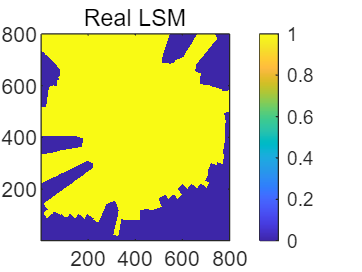

imagesc(LSM');
set(gca,'YDir','normal')
colorbar;
title('Real LSM')



fc = 28;%GHz


%beta1 = -18  - 20*log10(fc);
beta1 = -28  - 20*log10(fc);
altha1 = -2.2;
thegma1 = (4.64*exp(-0.0066*UAVheight))^2;
beta0 = 17.5 - 20*log10(40*pi*fc/3);
altha0 = -(46 - 7*log10(UAVheight))/10;
thegma0 = 6.25;
% thegma0 = 36;


Channel_LOS_Para = [beta1,altha1,thegma1];
Channel_NLOS_Para = [beta0,altha0,thegma0];
Channel_Para = [Channel_LOS_Para;Channel_NLOS_Para];
% 计算CGM每个位置上的信道参数。
CGM = create_CGM(LSM,UAVgrid_Bs_dist,Channel_Para);
CGM_mu = CGM(:,:,1);
CGM_var = CGM(:,:,2);


## Prior Map Calculation

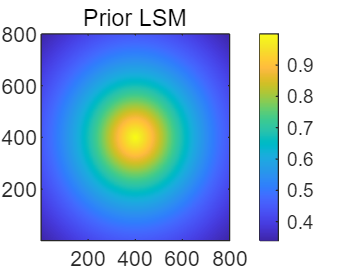

LSM_initial = LSMtheta_initial(UAVgrid_Bs_dist,UAVheight,BSHeight);
figure;
imagesc(LSM_initial);
set(gca,'YDir','normal')
colorbar;
title('Prior LSM')

## Grid Location Index

% Index 号给出其x，y的索引
% G_Index = [];

rows = 800; cols = 800; % 生成索引向量

% 使用 ndgrid 生成索引矩阵
[X, Y] = ndgrid(1:rows, 1:cols);
% 将索引矩阵转换为索引向量 
G_Index = [X(:), Y(:)];

% 显示索引向量
disp(G_Index);

     1     1
     2     1
     3     1
     4     1
     5     1
     6     1
     7     1
     8     1
     9     1
    10     1
    11     1
    12     1
    13     1
    14     1
    15     1
    16     1
    17     1
    18     1
    19     1
    20     1
    21     1
    22     1
    23     1
    24     1
    25     1
    26     1
    27     1
    28     1
    29     1
    30     1
    31     1
    32     1
    33     1
    34     1
    35     1
    36     1
    37     1
    38     1
    39     1
    40     1
    41     1
    42     1
    43     1
    44     1
    45     1
    46     1
    47     1
    48     1
    49     1
    50     1
    51     1
    52     1
    53     1
    54     1
    55     1
    56     1
    57     1
    58     1
    59     1
    60     1
    61     1
    62     1
    63     1
    64     1
    65     1
    66     1
    67     1
    68     1
    69     1
    70     1
    71     1
    72     1
    73     1
    74     1
    75     1
    76     1
    77     1

## Initial Mutual Information Calculation

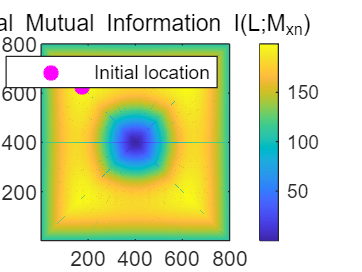

% 先验概率更新
LSM_prior = LSM_initial;
LSMlog_prior = log(LSM_prior./(1-LSM_prior));

I_Lphi_Mxn = zeros(800,800); % LSM地图，计算角度上的求和的互信息

for i = 1:800
    for j = 1:800
        xn = [i,j,UAVheight];
        % [H_L, H_sum] = Compute_PriorEntropy(LSM_prior); % 计算LSM地图先验熵
        % H_Lphi_Mxn = Compute_H_Lphi_Mxn( LSM_prior, xn, Channel_Para , BSloc);
        I_Lphi_Mxn(i,j) = Compute_I_Lphi_Mxn( LSM_prior, xn, Channel_Para , BSloc);
    end
end
% H_L_Mxn = Compute_H_L_Mxn(LSM_prior, xn, Channel_Para); % 计算LSM在栅格xn = (i,j)处测量获得的条件熵



% 展示初始互信息平面图
[Index1,Index2] = max(I_Lphi_Mxn);
figure;
imagesc(I_Lphi_Mxn');
set(gca,'YDir','normal');
colorbar;
title('Initial Mutual Information I(L;M_{xn})');

hold on;


%% 寻找寻找I_Lphi_Mxn中的最大值。
maxInitial_I = max(max(I_Lphi_Mxn));
[row1,col1] = find(I_Lphi_Mxn == maxInitial_I);
% scatter(row1(1),col1(1),'r*','LineWidth',2);
scatter(row1(3),col1(3),'magenta*','LineWidth',2);
hold off;
legend('Initial location');

## 根据初次测量更新LoS地图



x0 = [row1(3), col1(3), UAVheight];
input_LSM = is_LoSorNLoS(BSloc,x0,smallBldMap);
flag = -input_LSM + 2;
d0 = norm(x0 - BSloc);

mu_g = Channel_Para(:,1)+10.*Channel_Para(:,2).*log10(d0);
var_g = Channel_Para(:,3); 
var_meas = 0;

z0 = mu_g(flag) + sqrt(var_g(flag))*randn(1); % 获得一次测量



函数或变量 'LSMlog_prior' 无法识别。

LSMlog_prior = log(LSM_prior./(1-LSM_prior));
[updated_grid,LSM_posterior, LSMlog_posterior] = Update_LSM(LSMlog_prior, x0, z0, Channel_Para, LSM_initial, BSloc); % 在选出的测量位置测量来更新地图

figure;
imagesc(LSM_posterior');
set(gca,'YDir','normal');
colorbar;
title('Posterior LoS probability with z0');
hold on;
scatter(x0(1),x0(2),'magenta*','LineWidth',2);
legend('Initial location');

## Mutual Information Update

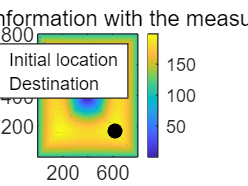

% 先找LSM地图更新了的栅格, 除了更新了的栅格之外，其他栅格不用计算互信息。
% Compute_I_Lphi_Mxn(LSM_posterior,);

[NUM_upa,~] = size(updated_grid);
for i = 1:NUM_upa % LSM地图，计算被更新的栅格角度上的求和的互信息
    xn = [updated_grid(i,1),updated_grid(i,2),UAVheight];
    I_Lphi_Mxn(xn(1),xn(2)) = Compute_I_Lphi_Mxn(LSM_posterior, xn, Channel_Para, BSloc);
end

figure;
imagesc(I_Lphi_Mxn');
set(gca,'YDir','normal');
colorbar;
title('Updated Mutual Information with the measurement z0');
hold on;
scatter(x0(1),x0(2),'magenta*','LineWidth',2);
% scatter(row1(2),col1(2),'filled','black','LineWidth',2);
scatter(row1(4),x0(1),'filled','black','LineWidth',2);
legend('Initial location','Destination');

## Route Calculation

xI = [x0(1),x0(2)-1];
% xF = [row1(2),col1(2)];
xF = [row1(4),x0(1)];

% X1 = [(xI(1)+1:xF(1))',ones(abs(xF(1)-xI(1)),1)*xF(2)]; % 路线1，直线连接
Temp1 = [400,400];
Ray = Ray_line;
Ray11 = Ray.Bresenham(xI(1),xI(2),Temp1(1),Temp1(2));
Ray12 = Ray.Bresenham(Temp1(1),Temp1(2),xF(1),xF(2));
X1 = [Ray11;Ray12]; % 路线1，直线连接

Temp2 = [400,750];
Ray = Ray_line;
Ray21 = Ray.Bresenham(xI(1),xI(2),Temp2(1),Temp2(2));
Ray22 = Ray.Bresenham(Temp2(1),Temp2(2),xF(1),xF(2));
X2 = [Ray21;Ray22]; % 路线2，往左上角绕，然后向下到目的地

Temp3 = [400,500];
Ray = Ray_line;
Ray31 = Ray.Bresenham(xI(1),xI(2),Temp3(1),Temp3(2));
Ray32 = Ray.Bresenham(Temp3(1),Temp3(2),xF(1),xF(2));
X3 = [Ray31;Ray32];

Temp4 = [627,627];
Ray = Ray_line;
Ray41 = Ray.Bresenham(xI(1),xI(2),Temp4(1),Temp4(2));
Ray42 = Ray.Bresenham(Temp4(1),Temp4(2),xF(1),xF(2));
X4 = [Ray41;Ray42];


I_X1 = I_Lphi_Mxn(X1(:,1)+ (X1(:,2)-1) * size(I_Lphi_Mxn,1));
D11 = norm(xI-Temp1);
D12 = norm(xF-Temp1);
I_X1_ratio = sum(I_X1)./(D11+D12);

I_X2 = I_Lphi_Mxn(X2(:,1)+ (X2(:,2)-1) * size(I_Lphi_Mxn,1));
D21 = norm(xI-Temp2);
D22 = norm(xF-Temp2);
I_X2_ratio = sum(I_X2)./(D21+D22);

I_X3 = I_Lphi_Mxn(X3(:,1)+ (X3(:,2)-1) * size(I_Lphi_Mxn,1));
D31 = norm(xI-Temp3);
D32 = norm(xF-Temp3);
I_X3_ratio = sum(I_X3)./(D31+D32);

I_X4 = I_Lphi_Mxn(X4(:,1)+ (X4(:,2)-1) * size(I_Lphi_Mxn,1));
D41 = norm(xI-Temp4);
D42 = norm(xF-Temp4);
I_X4_ratio = sum(I_X4)./(D41+D42);

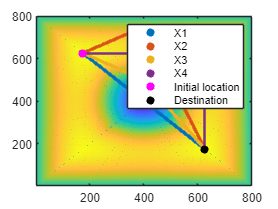


figure;
imagesc(I_Lphi_Mxn');
set(gca,'YDir','normal');
hold on;
scatter(X1(:,1),X1(:,2),4,"filled");
scatter(X2(:,1),X2(:,2),4,"filled");
scatter(X3(:,1),X3(:,2),4,"filled");
scatter(X4(:,1),X4(:,2),4,"filled");
scatter(xI(1),xI(2),'magenta*','LineWidth',2);
scatter(xF(1),xF(2),'filled','black','LineWidth',2);

legend('X1','X2','X3','X4','Initial location','Destination');

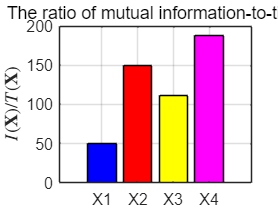


figure;
data = [I_X1_ratio,I_X2_ratio,I_X3_ratio, I_X4_ratio];
x_labels = {'X1', 'X2', 'X3', 'X4'}; % 横坐标标签
y_label = '$I(\mathbf{X})/T(\mathbf{X})$'; % 纵坐标标签
b = bar(data);
b.FaceColor = 'flat';
b.CData = [0, 0, 1;    % 蓝色
           1, 0, 0;    % 红色
           1, 1, 0;    % 黄色
           1, 0, 1];   % 紫色;

xticks(1:length(data)); % 设置横坐标刻度
xticklabels(x_labels); % 设置横坐标标签

% 设置纵坐标标签
ylabel(y_label, Interpreter="latex");

grid on; % 添加网格
set(gca, 'FontSize', 12); % 设置字体大小
title('The ratio of mutual information-to-time');